load sampleEEGdata.mat

electrode = 1;
f = [5,25];

signal = squeeze(EEG.data(electrode,:,:));

## **Wavelet Creation**

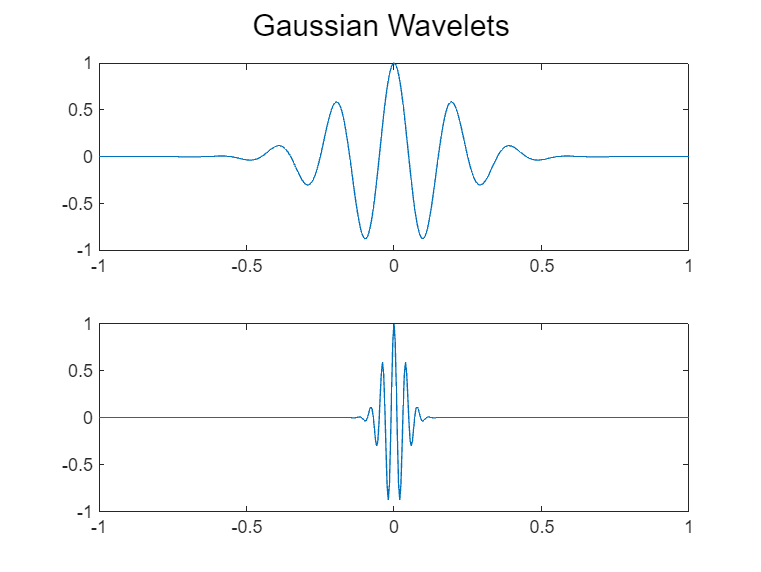

time = -1:1/EEG.srate:1;

m_wlet_space = zeros([length(f), length(time)]);
hw_size = ceil(length(time)/2);

for i = 1:2
    s = 6/(2*pi*f(i));
    A(i) = 1/sqrt(s*sqrt(pi));
    g_window = exp(-time.^2./(2*s^2));
    s_wave = exp(2*pi*1i*f(i).*time);
    m_wlet_space(i,:) = g_window.*s_wave;
end

figure;
subplot(211)
plot(time, real(m_wlet_space(1,:)));
subplot(212)
plot(time, real(m_wlet_space(2,:)));

sgtitle("Gaussian Wavelets")

## **Complex Morlet Wavelet Convolution**

n_conv = EEG.pnts + length(time) - 1;
figure;

fft_s = fft(signal, n_conv)';
fft_w = fft(m_wlet_space', n_conv)';
fft_c = zeros([EEG.trials,n_conv,length(f)]);

for i = 1:length(f)
    fft_c(:,:,i) = fft_s.*fft_w(i,:);
end

conv_result = ifft(fft_c,n_conv,2)*sqrt(s)/10;
conv_result = fliplr(conv_result(:,hw_size:end-hw_size + 1,:));

## **filter-Hilbert Method**

**1) Designing the filter**

nyquist = EEG.srate/2;
lower_filter_bound = 4; % Hz
upper_filter_bound = 6; % Hz
transition_width   = 0.2;
filter_order       = round(3*(EEG.srate/lower_filter_bound));

% create the filter shape (this is explained more in the text around figure 14.4)
ffrequencies  = [ 0 (1-transition_width)*lower_filter_bound lower_filter_bound upper_filter_bound (1+transition_width)*upper_filter_bound nyquist ]/nyquist;
idealresponse = [ 0 0 1 1 0 0 ];
filterweights = firls(filter_order,ffrequencies,idealresponse);

nyquist = EEG.srate/2;
lower_filter_bound = 25; % Hz
upper_filter_bound = 26; % Hz
transition_width   = 0.2;
filter_order       = round(3*(EEG.srate/lower_filter_bound));

% create the filter shape (this is explained more in the text around figure 14.4)
ffrequencies  = [ 0 (1-transition_width)*lower_filter_bound lower_filter_bound upper_filter_bound (1+transition_width)*upper_filter_bound nyquist ]/nyquist;
idealresponse = [ 0 0 1 1 0 0 ];
filter2weights = firls(filter_order,ffrequencies,idealresponse);

**2) Applying filter-Hilbert Method**

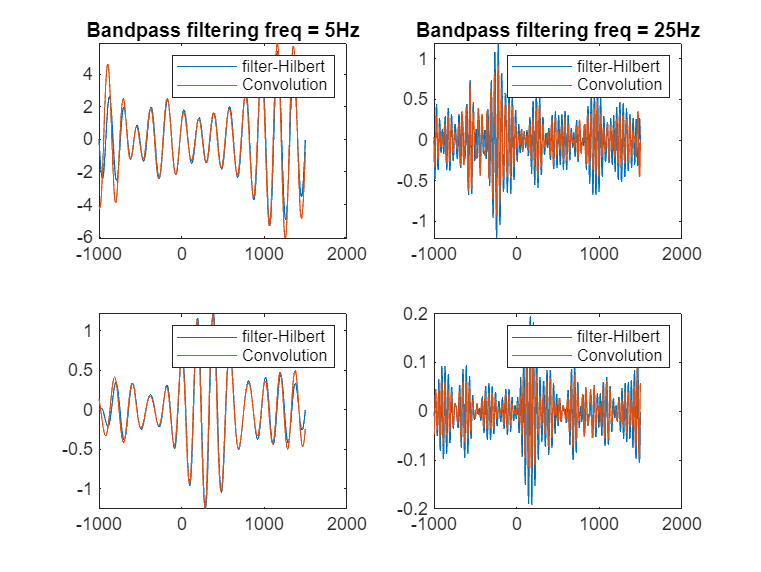

filtered_signal = filtfilt(filterweights,1,signal);
hf_result1 = hilbert(filtered_signal);
filtered_signal = filtfilt(filter2weights,1,signal);
hf_result2 = hilbert(filtered_signal);

figure;
subplot(221)
plot(EEG.times, real(hf_result1(:,23)))
hold on
plot(EEG.times, real(conv_result(23,:,1)))
hold off
legend("filter-Hilbert", "Convolution")

title("Bandpass filtering freq = 5Hz")

subplot(222)
plot(EEG.times, real(hf_result2(:,23)))
hold on
plot(EEG.times, real((conv_result(23,:,2))))
hold off
legend("filter-Hilbert", "Convolution")
title("Bandpass filtering freq = 25Hz")


subplot(223)
mean_conv_result = squeeze(mean(conv_result));
mean_hf_result = squeeze(mean(hf_result1,2));
plot(EEG.times, real(mean_hf_result));
hold on
plot(EEG.times, real(mean_conv_result(:,1)))
hold off
legend("filter-Hilbert", "Convolution")

subplot(224)
mean_conv_result = squeeze(mean(conv_result));
mean_hf_result2 = squeeze(mean(hf_result2,2));
plot(EEG.times, real(mean_hf_result2));
hold on
plot(EEG.times, real(mean_conv_result(:,2)))
hold off
legend("filter-Hilbert", "Convolution")

A = [2 3 1 4; 1 2 1 6; 4 7 3 10]

A =      2     3     1     4
     1     2     1     6
     4     7     3    10


rref(A')

ans =      1     0     0
     0     1     0
     0     0     1
     0     0     0



B = [2 1 4; 3 2 7; 1 1 3; 4 6 10]

B =      2     1     4
     3     2     7
     1     1     3
     4     6    10


rref(B)

ans =      1     0     0
     0     1     0
     0     0     1
     0     0     0



C = [2 4 1;6 8 3; 1 2 0]'

C =      2     6     1
     4     8     2
     1     3     0


rref(C')

ans =      1     0     0
     0     1     0
     0     0     1


D = [1 -3 2 2 1; 0 3 6 0 -3; 2 -3 -2 4 4; 3 -6 0 6 5; -2 9 2 -4 -5]

D =      1    -3     2     2     1
     0     3     6     0    -3
     2    -3    -2     4     4
     3    -6     0     6     5
    -2     9     2    -4    -5


rref(D)

ans =     1.0000         0         0    2.0000    1.3333
         0    1.0000         0         0   -0.1667
         0         0    1.0000         0   -0.4167
         0         0         0         0         0
         0         0         0         0         0
